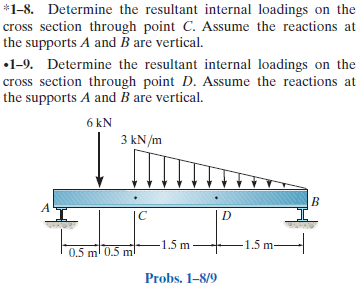

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-1-problem-8P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-1-problem-8P-solution-9780136022305) 

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-1-problem-9P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-1-problem-9P-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# load data

w1 = findpoly(1, 'thru', [u.m -3*u.kN/u.m], 'thru', [4*u.m 0]);

# beam

b = beam;
b = b.add('reaction', 'force', 'Ra', 0);
b = b.add('reaction', 'force', 'Rb', 4*u.m);
b = b.add('concentrated', 'force', -6*u.kN, 0.5*u.m);
b = b.add('distributed', 'force', w1, [1 4]*u.m);
b.L = 4*u.m;

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('Mode', 'factor');

# elastic curve

y

$$y(x) = \left\{ \begin{array}{cl} -\frac{x\,\left(1161\,m^{2}-200\,x^{2}\right)}{160\,\text{E}\,\text{I}}\,\mathrm{kN} & \text{ if }x\leq \frac{1}{2}\,m\\ \frac{40\,x^{3}+240\,x^{2}\,m-1281\,x\,m^{2}+20\,m^{3}}{160\,\text{E}\,\text{I}}\,\mathrm{kN} & \text{ if }x\in \left(\frac{1}{2}\,m,m\right]\\ \frac{\left(x-4\,m\right)\,\left(4\,x^{4}-64\,x^{3}\,m+144\,x^{2}\,m^{2}+896\,x\,m^{3}+m^{4}\right)}{480\,\text{E}\,\text{I}}\,\frac{\mathrm{kN}}{m^{2}} & \text{ if }m<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} -\frac{3\,\left(387\,m^{2}-200\,x^{2}\right)}{160\,\text{E}\,\text{I}}\,\mathrm{kN} & \text{ if }x\leq \frac{1}{2}\,m\\ \frac{3\,\left(40\,x^{2}+160\,x\,m-427\,m^{2}\right)}{160\,\text{E}\,\text{I}}\,\mathrm{kN} & \text{ if }x\in \left(\frac{1}{2}\,m,m\right]\\ \frac{20\,x^{4}-320\,x^{3}\,m+1200\,x^{2}\,m^{2}+640\,x\,m^{3}-3583\,m^{4}}{480\,\text{E}\,\text{I}}\,\frac{\mathrm{kN}}{m^{2}} & \text{ if }m<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} \frac{15\,x}{2}\,\mathrm{kN} & \text{ if }x\leq \frac{1}{2}\,m\\ \frac{3\,\left(x+2\,m\right)}{2}\,\mathrm{kN} & \text{ if }x\in \left(\frac{1}{2}\,m,m\right)\\ -\frac{\left(x-4\,m\right)\,\left(-x^{2}+8\,x\,m+2\,m^{2}\right)}{6}\,\frac{\mathrm{kN}}{m^{2}} & \text{ if }m\leq x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} \frac{15}{2}\,\mathrm{kN} & \text{ if }x\leq \frac{1}{2}\,m\\ \frac{3}{2}\,\mathrm{kN} & \text{ if }x\in \left(\frac{1}{2}\,m,m\right)\\ \frac{x^{2}-8\,x\,m+10\,m^{2}}{2}\,\frac{\mathrm{kN}}{m^{2}} & \text{ if }m\leq x \end{array}\right.$$

w

$$w(x) = \left\{ \begin{array}{cl} 0 & \text{ if }x<m\\ \left(x-4\,m\right)\,\frac{\mathrm{kN}}{m^{2}} & \text{ if }m\leq x \end{array}\right.$$

# reactions and hinges

ra_vpa = vpa(ra) %#ok<NASGU> 

$$ra\_vpa = \left(\begin{array}{cc} \mathrm{Ra} & 7.5\,\mathrm{kN}\\ \mathrm{Rb} & 3.0\,\mathrm{kN} \end{array}\right)$$

ha

 
ha =
 
Empty sym: 0-by-2
 


# shear and moment diagram

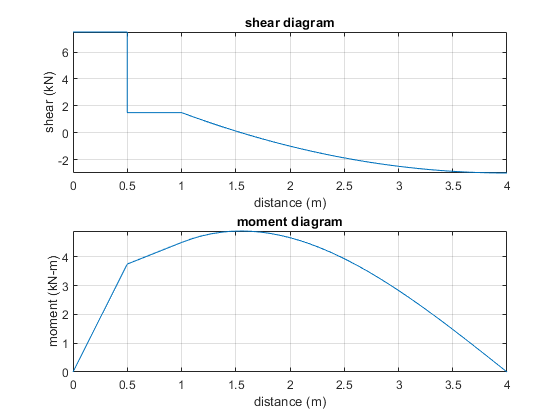

beam.shear_moment(m, v, [0 b.L], {'kN' 'm'});

# clean up

addvar(y);
assume(old_assum);
clear old_assum;
clear ra_vpa;